## **环境交互测试实验3：多无人机实时任务分配**

%% 添加必要的路径
run('path_add.m')
clear,clc

% 加载数据
filename = "Forest_data.mat";
% 使用exist函数检查文件是否存在  
if exist(filename, 'file') == 2  
    load Forest_environment\Forest_data.mat 
else  
    run("Forest_environment\Forest_generate.m")
    load Forest_environment\Forest_data.mat
end
if exist("Env_test_Data\fieldShape.mat", 'file') == 2  
    load Env_test_Data\fieldShape.mat
else  
    [points,points_field] = fieldShape_generate(trees, field_tree);
    save Env_test_Data\fieldShape.mat points_field points
end

## 设计任务分配过程

% 得到待侦察目标位置,以树的顶端作为搜索目标
points_target = information_tree(:,1:3);
for i=1:length(trees)
    points_target(i,3) = points_target(i,3)+trees(i).height;
end

% 初始化无人机群
numofUAVs = 3;
uavs = [];
max_speed = 200;
max_range = 60;
max_altitude = 310;
max_power = 5000;
max_load = 25;
k_up = 0.05;
k_down = 0.01;
k_around = 0.03;
dt = 0.1;
uav_0 = uav(max_speed,max_range,max_altitude,max_power,max_load,k_up,k_down,k_around,dt);
for i=1:numofUAVs
    uavs = [uavs;uav_0.current_properties_reset(8/10*max_speed,0,max_power,max_load/2,[-10,-10,1])];
end

% 任务分配过程
power_check = false;
power_alert = 500; % 油量预警
for i=1:length(uavs)
    if uavs(i).power(end) > power_alert
        power_check = true;
        break
    end
end
mession_completed = 0; % 完成的任务个数
task_information = TaskAllocator(points_target, numofUAVs, 1);
evafun = @(x)sum(x);
while power_check
    % 开始任务规划过程
    task_information = task_information.dataforAllocator_init(uavs); % 利用欧几里得距离初始化
    temp_num=randi(10);  % 随机选择某个位置作为待执行任务目标点
    assignment = task_information.allocateTasks(evafun, uavs, power_alert);  % 当前任务分配
    uavs(assignment(temp_num)) = uavs(assignment(temp_num)).FlyToNextPoint_flexible_try(...
        points_target(temp_num,:),[],[],trees,field_tree);
    mession_completed = mession_completed + 1;
    power_check = false;
    for i=1:length(uavs)
        if uavs(i).power(end) > power_alert
            power_check = true;
            break
        end
    end
end

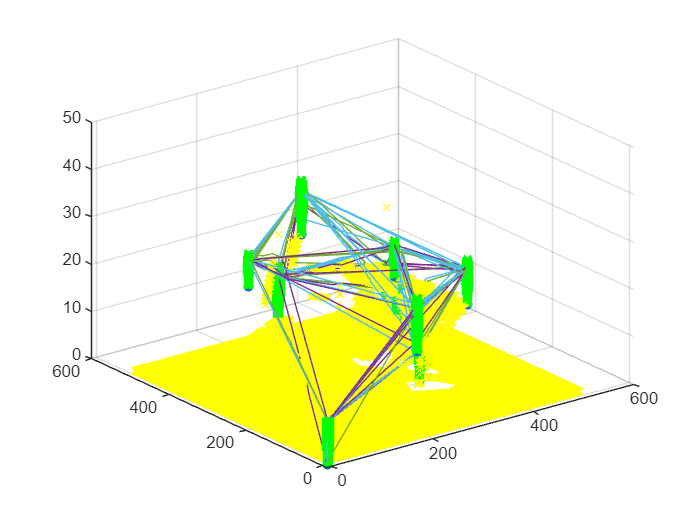

% 让我们将环境和轨迹简单的画出来吧
figure(1)
scatter3(information_tree(:,1),information_tree(:,2),information_tree(:,3),'filled','o')
hold on
scatter3(points(:,1),points(:,2),points(:,3),'green','x')
scatter3(points_field(:,1),points_field(:,2),points_field(:,3),'yellow','x')
for i=1:length(uavs)
    plot3(uavs(i).position(:,1),uavs(i).position(:,2),uavs(i).position(:,3))
end
hold off

calculatePathLength(uavs(3).position)

ans = 11680